# **Robust Control with Nominal Mixed-Sensitivity Design**

### Dataset Upload

clc; clear all; close all

L_nom = 36.5e-6;
Lm_nom = 0.99*L_nom/sqrt(2.33);
C_nom = 100e-06;


load("dataset\20_30.mat"); C1 = C; k1 = k; Lm1 = k1*L_nom/sqrt(2.33);
load("dataset\25_35.mat"); C2 = C; k2 = k; Lm2 = k2*L_nom/sqrt(2.33);
load("dataset\30_35_40.mat"); C3 = C; k3 = k; Lm3 = k3*L_nom/sqrt(2.33);
load("dataset\45_50_60.mat"); C4 = C; k4 = k; Lm4 = k4*L_nom/sqrt(2.33);

Lm_bm = mean([Lm1, Lm2, Lm3, Lm4]);
C_bm = mean([C1, C2, C3, C4]);

fprintf('Variation to Real Value\n Lm: %0.3f %%\t C: %0.3f %%', (1-Lm_bm/Lm_nom)*100, (1-C_bm/C_nom)*100);

Variation to Real Value
 Lm: 33.533 %	 C: -19.428 %

### System Definition

DuCy=30; 
I_Lo=0; V_Co=0;
Vg=5; Vd=0.7;
Vs=[Vg Vd];
X=[I_Lo V_Co];


[~,~,~,~,Gnom] =flyback_ss(Vs,X,DuCy,Lm_bm,C_bm)

Gnom =
 
           3.511e10
  ---------------------------
  s^2 + 1.907e04 s + 8.244e10
 
Continuous-time transfer function.



omega_n = sqrt(8.244e10);
xi_n = 1.907e4/(2*omega_n);


xi = ureal('xi',xi_n,'Percentage',30)

xi =   Uncertain real parameter "xi" with nominal value 0.0332 and variability [-30,30]%.


omega = ureal('omega', omega_n,'Percentage',30)

omega =   Uncertain real parameter "omega" with nominal value 2.87e+05 and variability [-30,30]%.



G = tf(3.51e10,[1 2*xi*omega omega^2])

G =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    omega: Uncertain real, nominal = 2.87e+05, variability = [-30,30]%, 3 occurrences
    xi: Uncertain real, nominal = 0.0332, variability = [-30,30]%, 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.



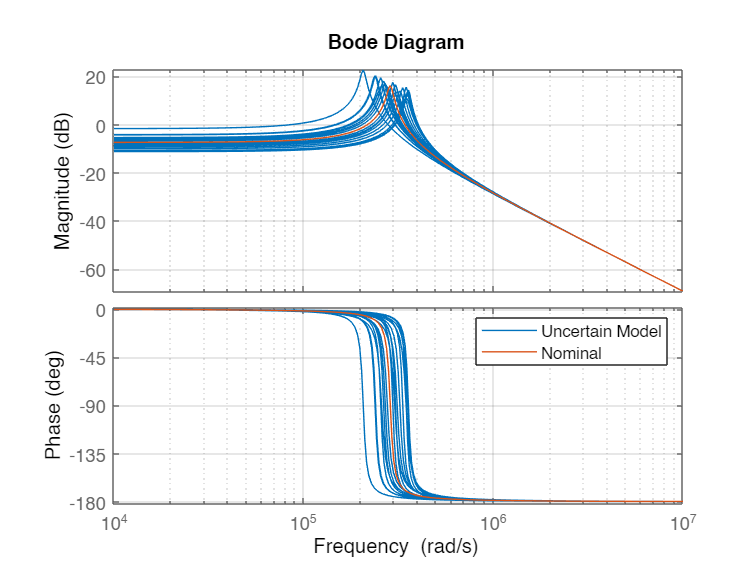


bode(G, G.Nominal)
grid on
legend('Uncertain Model', 'Nominal')

**Specify Tunable Elements**

The target control bandwidth is 10 rad/s. Create a tunable PID controller and fix its derivative filter time constant to  (10 times the bandwidth) so that there are only three gains to tune (proportional, integral, and derivative gains).

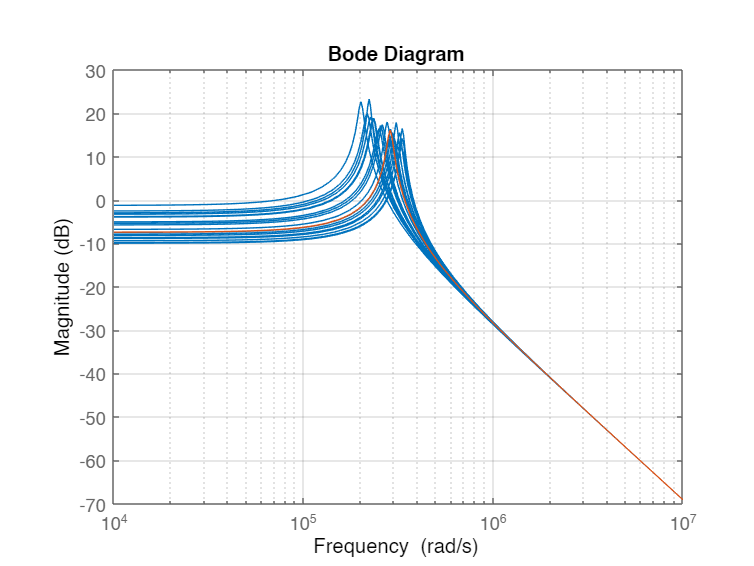

bodemag(G,getNominal(G))
grid on

C = tunablePID2('C','pid');
C.Tf.Value = 0.01;  C.Tf.Free = false;  % fix Tf=0.01


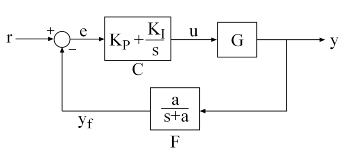

Construct a tunable model `T0` of the closed-loop transfer from `r` to `y`. Use an "analysis point" block to mark the location `u` where the disturbance enters.

AP = AnalysisPoint('u');
CL0 = feedback(G*AP*C,1,2,1,+1);
CL0 = CL0(:,1);
CL0.u = 'r';  CL0.y = 'y';

**Specify Design Requirements**

The gain of the open-loop response  is a key indicator of the feedback loop behavior. The open-loop gain should be high (greater than one) inside the control bandwidth to ensure good disturbance rejection, and should be low (less than one) outside the control bandwidth to be insensitive to measurement noise and unmodeled plant dynamics. Accordingly, use three requirements to express the control objectives:

- "Tracking" requirement to specify a response time of about 0.2 seconds to step changes in `r`

- "MaxLoopGain" requirement to force a roll-off of -20 dB/decade past the crossover frequency 10 rad/s

- "MinLoopGain" requirement to adjust the integral gain at frequencies below 0.1 rad/s.

s = tf('s');
wc = 8*10^5; % target crossover frequency

% Tracking
R1 = TuningGoal.Tracking('r','y',1000/wc);

% Bandwidth and roll-off
R2 = TuningGoal.MaxLoopGain('u',wc/s);

% Disturbance rejection

R3 = TuningGoal.MinLoopGain('u',wc/s);
R3.Focus = [0 10];

R4 = TuningGoal.Margins('u',10,60);
% The feedback loop should have 6dB of gain margin and 45 degrees of phase margin

- **Crossover and Rolloff.** Use a target loop shape with its 0 dB crossover frequency *ω**c* between the previous two frequency ranges. Ensure that the target loop shape rolls off with a slope between –20 dB/decade and –30 dB/decade near *ω**c*. This rolloff helps keep phase lag approximately between –130° and –90° near crossover for good phase margins.

opt = systuneOptions('RandomStart',10);
rng(0), [CL,fSoft] = systune(CL0,R1,[R2 R3 R4] ,opt);

Nominal tuning:
Design 1: Soft = 1.08, Hard = 0.87764
Design 2: Soft = 1.08, Hard = 0.80504
Design 3: Soft = 1.08, Hard = 0.97262
Design 4: Soft = 1.08, Hard = 0.99935
Design 5: Soft = 1.08, Hard = 0.99144
Design 6: Soft = 1.08, Hard = 0.91162
Design 7: Soft = 13.1, Hard = 1.315
Design 8: Soft = 1.08, Hard = 0.99617
Design 9: Soft = 1.08, Hard = 0.95874
Design 10: Soft = 1.08, Hard = 0.79657
Design 11: Soft = 1.08, Hard = 0.87665

Robust tuning of Design 11:
Soft: [1.08,Inf], Hard: [0.877,2.48], Iterations = 186
Soft: [1.7,Inf], Hard: [1,1.69], Iterations = 36
Soft: [2.17,Inf], Hard: [1.16,1.16], Iterations = 32
Final: Soft = 2.17, Hard = 1.1607, Iterations = 254

Robust tuning of Design 10:
Soft: [1.08,Inf], Hard: [0.797,1.64], Iterations = 174
Soft: [1.72,Inf], Hard: [1,1.69], Iterations = 32
Soft: [2.19,Inf], Hard: [1.16,1.16], Iterations = 32
Final: Soft = 2.19, Hard = 1.1607, Iterations = 238

Robust tuning of Design 5:
Soft: [1.08,Inf], Hard: [0.991,3.3], Iterations = 101
Soft: [

showTunable(CL)

C =
 
                       1                s    
  u = Kp (b*r-y) + Ki --- (r-y) + Kd -------- (c*r-y)
                       s              Tf*s+1 

  with Kp = -308, Ki = 3.44e+04, Kd = 3.08, Tf = 0.01, b = 1.07, c = 1.07
 
Name: C
Continuous-time 2-DOF PIDF controller in parallel form.


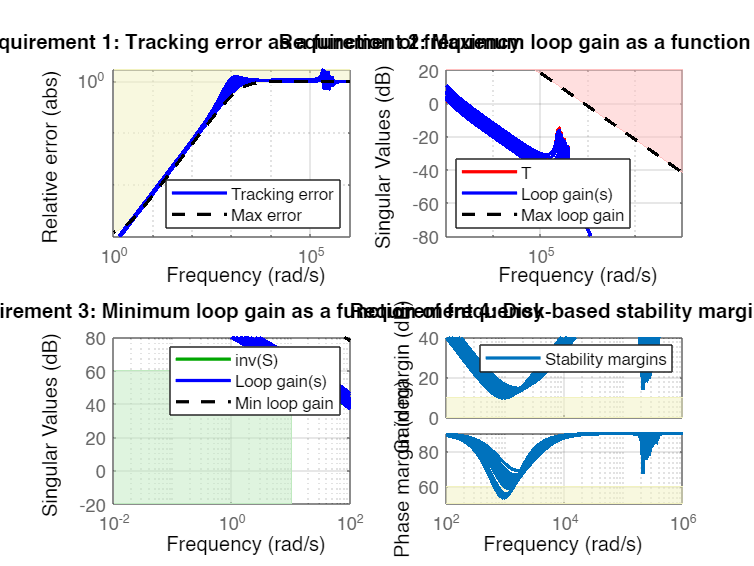

figureK
viewGoal([R1 R2 R3 R4],CL)

**Validate Results**

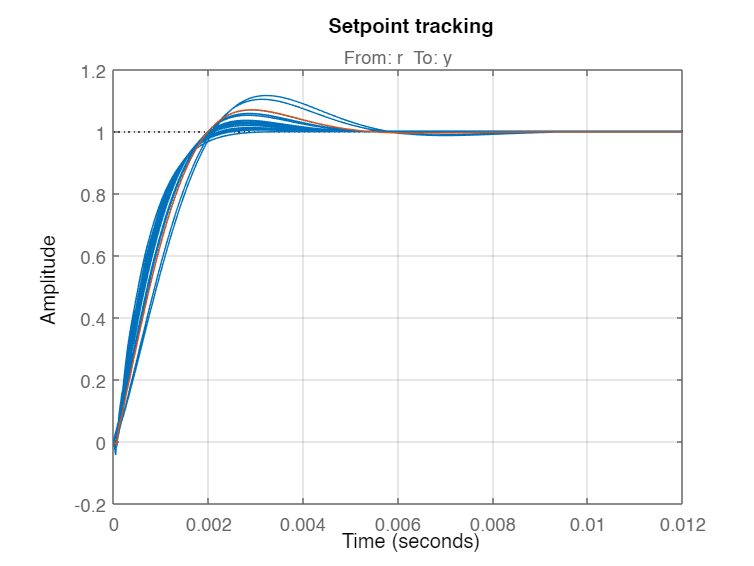

figure

step(CL,getNominal(CL))
grid on
title('Setpoint tracking')

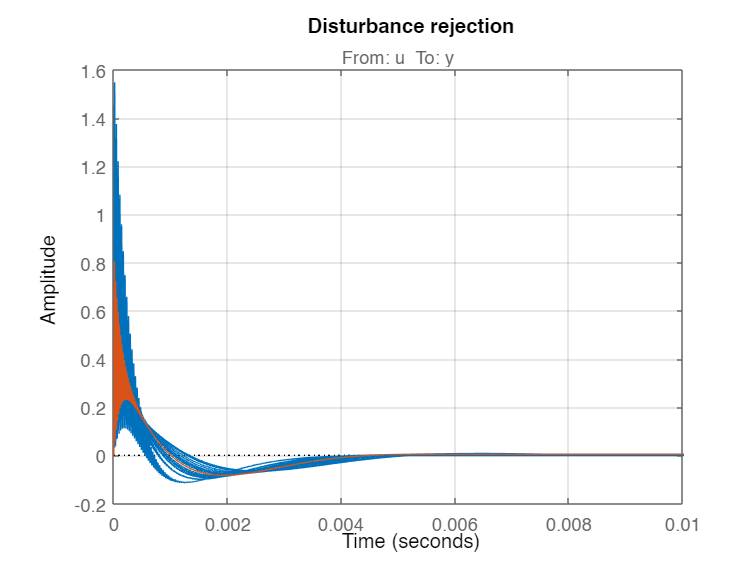

D = getIOTransfer(CL,'u','y');
figure 
step(D,getNominal(D))
grid on
title('Disturbance rejection')